%Load the image
image = load('abdomen.mat');
abd = image.abdomen;
roi = image.roi;

  Columns 1 through 36

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

%Load dataset containing fat pixels
fat = load('fatPoints.mat');
x1 = fat.x1;
x2 = fat.x2;
y = fat.y;

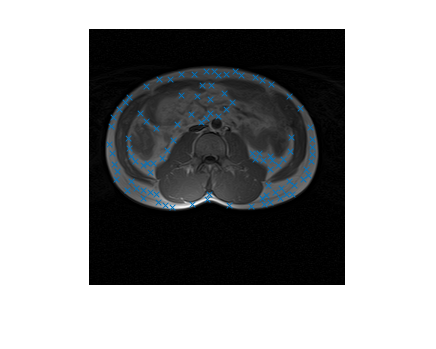

%Plot the abdominal scan together with the fat points
figure();
imshow(abd);
hold on
plot(x1, x2, 'x');
hold off;

%Perform Thin Plate Splines regression on fat points to identify regularization parameter
%lambda with 5, 10 and 20 degrees of freedom
data = [x1; x2; double(y)]';
lambdas = logspace(0, 5.3, 100);
dfList = zeros(1, length(lambdas));
for i = 1:length(lambdas)
    [~, df] = ThinPlateSplines(data, lambdas(i), 0, 1, 255);
    dfList(i) = df;
end
[~, I5] = min(abs(dfList - 5));
[~, I10] = min(abs(dfList - 10));
[~, I20] = min(abs(dfList - 20));

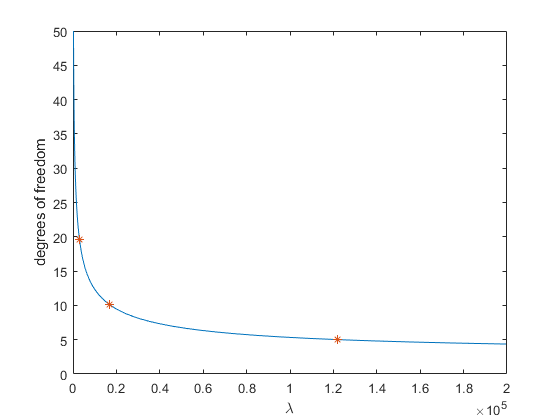

%Plot the number of degrees of freedom as a function of lambda
figure();
plot(lambdas, dfList);
hold on;
x = [lambdas(I5) lambdas(I10) lambdas(I20)];
y = [dfList(I5) dfList(I10) dfList(I20)];
plot(x, y, '*');
yticks(0:5:50);
ylim([0 50]);
xlabel("\lambda");
ylabel("degrees of freedom");
hold off;

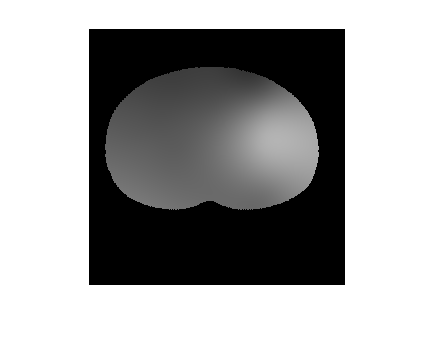

%Perform Thin Plate Splines regression with the 3 values of the
%regularization parameter
lambda = lambdas(I20);
[F, df] = ThinPlateSplines(data, lambda, 0, 1, 255);
F = uint8(F).*roi;

imshow(F);